# ASSIGNMENT 3

AMRUTH. G [240112]

---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

 PROBLEM-1                                               20

                                       G(s)   =       ----------------------

                                                            s(s + 2)(s + 5)

P1(a)

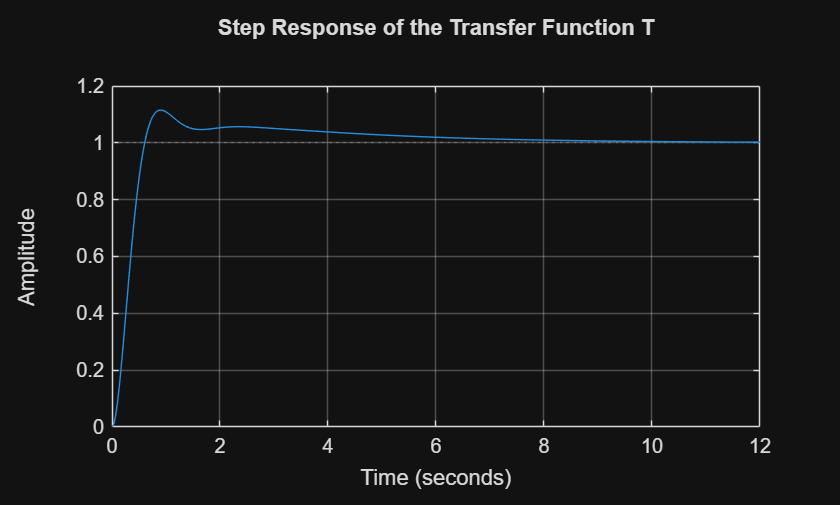

num = [20];
den = [1 7 10 0];
G = tf(num, den);

C = pidtune(G, 'PID');
T = feedback(C*G, 1);

figure; step(T); grid on;
title('Step Response of the Transfer Function T');


fprintf('kp : %.4f     ki : %.4f     kd : %.4f', C.kp, C.ki, C.kd);

kp : 1.7500     ki : 0.4504     kd : 1.0036


info = stepinfo(T);
disp('Step Response Characteristics:');

Step Response Characteristics:


fprintf('Overshoot     = %.4f %%\n', info.Overshoot);

Overshoot     = 11.5379 %


fprintf('Settling Time = %.4f seconds\n', info.SettlingTime);

Settling Time = 5.9509 seconds


fprintf('Rise Time     = %.4f seconds\n', info.RiseTime);

Rise Time     = 0.4083 seconds



% My final PID parameters :
kp = 1.75; ki = 0.45; kd = 1;

P1(b)

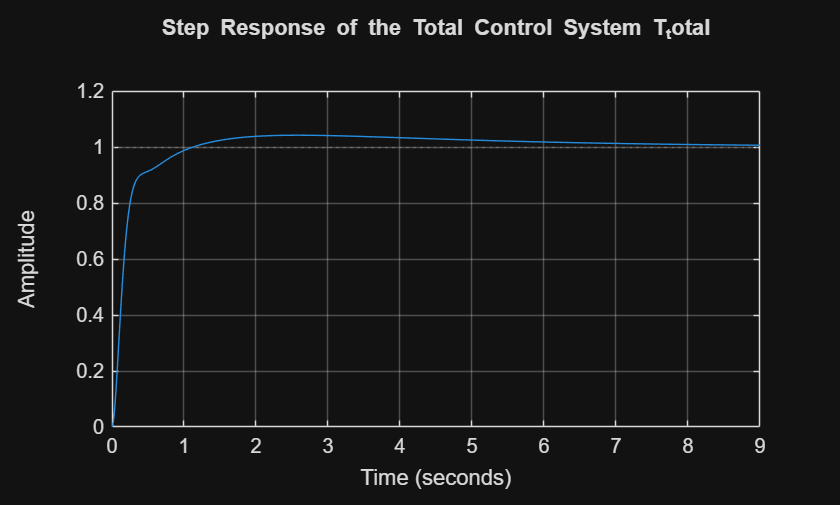

% My final PID parameters :
kp = 1.75; ki = 0.45; kd = 1;
C_pid = pid(kp, ki, kd);
T_pid = feedback(C_pid*G, 1);
kc = 6; z = 3; p = 15;
C_lead = tf(kc*[1 z], [1 p]);
C_total = C_lead * C_pid;

T_total = feedback(C_total * G, 1);
figure; step(T_total); grid on;
title('Step Response of the Total Control System T_total');

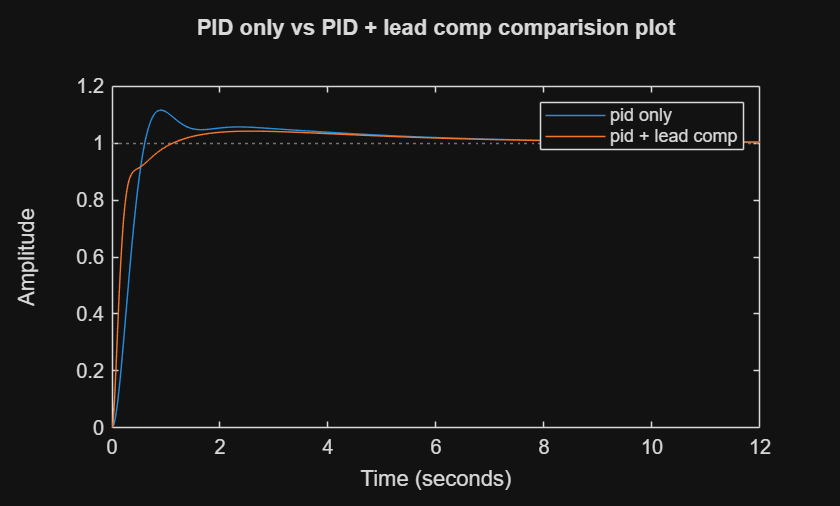

figure;
step(T_pid); hold on; step(T_total);
legend('pid only', 'pid + lead comp');
title('PID only vs PID + lead comp comparision plot');

P1(c)

info_total = stepinfo(T_total);
info_pid = stepinfo(T_pid);
disp('Comparision table PID only vs PID + lead compensator :');

Comparision table PID only vs PID + lead compensator :


fprintf('                 PID only       |  PID + lead comp\n')

                 PID only       |  PID + lead comp


fprintf('Overshoot     : %.4f %%       | %.4f %%\n', info_pid.Overshoot, info_total.Overshoot);

Overshoot     : 11.5978 %       | 4.2031 %


fprintf('Settling Time : %.4f seconds  | %.4f seconds\n', info_pid.SettlingTime, info_total.SettlingTime);

Settling Time : 5.9470 seconds  | 5.6640 seconds


fprintf('Rise Time     : %.4f seconds  | %.4f seconds\n', info_pid.RiseTime, info_total.RiseTime);

Rise Time     : 0.4090 seconds  | 0.3492 seconds



% How Lead componsator improved the step response ?
%   Ans. adding a zero close to origin reduced the overshoot, the pole has not much effect

P1(d)

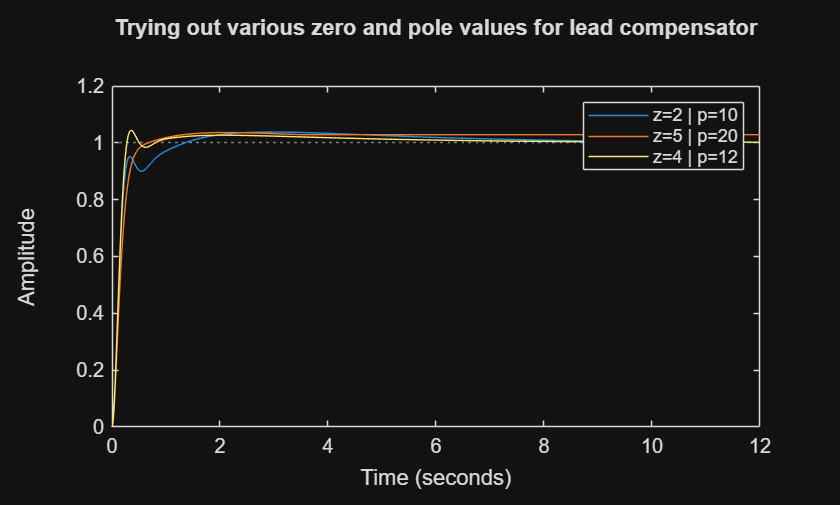

T1 = feedback(C_pid * tf(kc*[1 2], [1 10]) * G, 1);
T2 = feedback(C_pid * tf(kc*[1 5], [1 20]) * G, 1);
T3 = feedback(C_pid * tf(kc*[1 4], [1 12]) * G, 1);

figure; hold on;
step(T1); step(T2); step(T3);
legend('z=2 | p=10', 'z=5 | p=20', 'z=4 | p=12')
title('Trying out various zero and pole values for lead compensator');


% How the zero-pole placement affects the speed of response ? 
%   Ans. a zero closer to origin : reduces overshoot, negligible effect on rise time and settling time
%        a pole farther from origin : increases rise time and settling time
%        a pole closer to origin : significantly increases overshoot and settling time

PROBLEM-2                                          50

                                   G(s)   =    --------------------------

                                                   (s + 1)(s + 3)( s + 8)

P2(a)

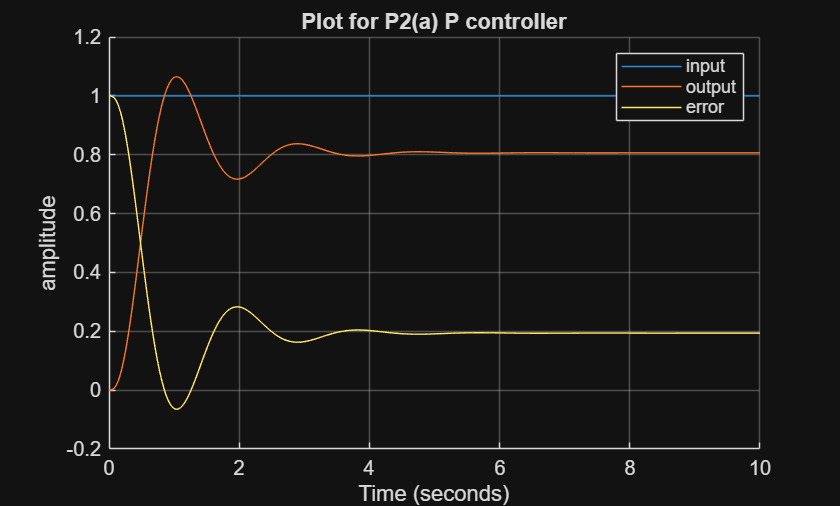

num = [50];
den = [1 12 35 24];
G = tf(num, den);
T_p = feedback(G * tf([2], [1]), 1);

t = 0:0.01:10; 
[y, t] = step(T_p, t);
r = ones(size(t));
e = r - y;  

figure; hold on;
plot(t, r); plot(t, y); plot(t, e);
legend('input', 'output', 'error');
title('Plot for P2(a) P controller');
xlabel('Time (seconds)');
ylabel('amplitude');
grid on;


ess = 1 - dcgain(T_p);
% ess = lim (s-->0) s(R(s) - Y(s)) = 1 - Y(0)
fprintf('steady state error : %.4f', ess);

steady state error : 0.1935

kc = 1; z = 1; p = 0.1; kp = 2;
C_lag = tf(kc*[1 z], [1 p]);

P2(b)

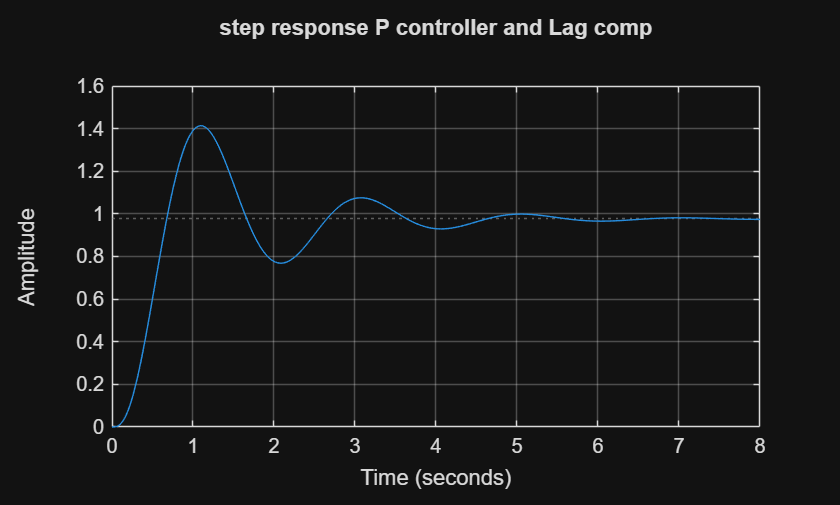

T_lag = feedback(kp * G * C_lag, 1);
figure; step(T_lag); grid on;
title('step response P controller and Lag comp');

ess_p = ess;
ess_p_lag = 1 - dcgain(T_lag);
error_reduction = 100 * (1 - ess_p_lag/ess_p);
st_p = stepinfo(T_p).SettlingTime;
st_p_lag = stepinfo(T_lag).SettlingTime;

P2(c)

disp('Comparision table P vs P + lag :')

Comparision table P vs P + lag :


fprintf('                       P     |  P + lag\n');

                       P     |  P + lag


fprintf('ss error      :    %.4f    |  %.4f  \n', ess_p, ess_p_lag);

ss error      :    0.1935    |  0.0234  


fprintf('Settling time :    %.4f s  |  %.4f s\n', st_p, st_p_lag);

Settling time :    3.2198 s  |  5.2126 s


fprintf('improvement in ss error : %.4f %%\n', error_reduction);

improvement in ss error : 87.8906 %



% Why lag compensator reeduces ss error ?
%   Ans. with P and Lag, we have C(s)G(s) = k50(s + z) / (s + 1)(s + 3)(s + 8)(s + p)
%        where k = kp * kc. and C(0)G(0) = 50kz/24p T(0) = C(0)G(0) / 1 + C(0)G(0)...
%        for k = 2; z = 1; p = 0.1 ==> T(0) = 0.9766.
%        the pole value being so small (p = 0.1), made T(0) ~ 1;
% Settling time has increased with lag compensator
% Response (rise time) is pretty much the same

P2(d)

figure;
step(T_lag); hold on;

p = 0.01

p = 0.0100

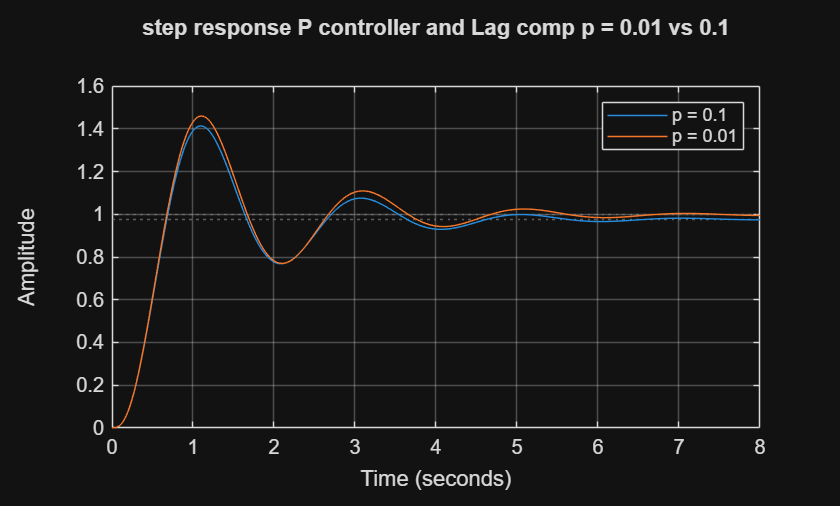

C_lag = tf(kc*[1 z], [1 p]);
T_lag = feedback(kp * G * C_lag, 1);

step(T_lag); grid on;
title('step response P controller and Lag comp p = 0.01 vs 0.1');
legend('p = 0.1', 'p = 0.01');


% Reducing pole to 0.01 moves the ss error closer to 0 but increases settling time a lot
% compared to p = 0.1

% Trade off :
% Rise time is pretty much the same with or without lag comp, but settling time increases
% significantly. but on the brighter side the ss error almost nullifys 
G = tf([1], [1 0.5]);
C_fb = pid(2, 1, 0);
T_fb = feedback(G * C_fb, 1);

PROBLEM-3                                       1

                                       G(s)   =    ----------

                                                        s  + 0.5

P3(a)

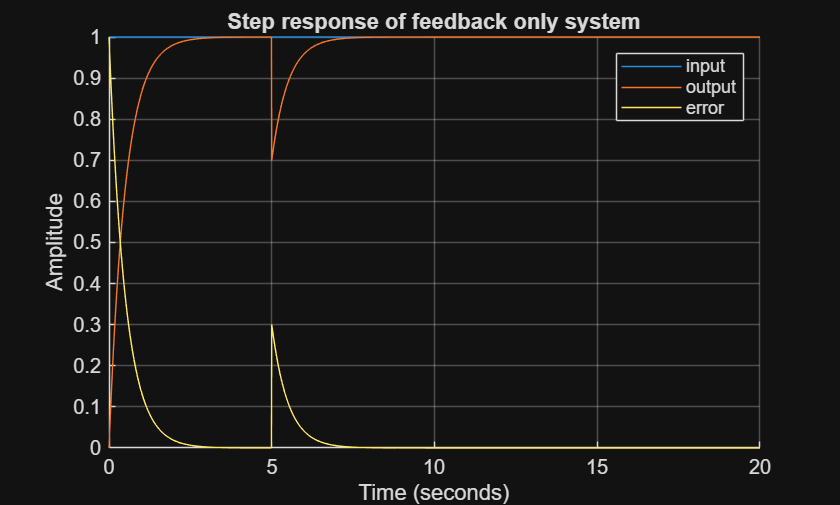

%   Y(s)        GC           D
%  ------  =  ------  -  ---------
%   X(s)      1 + GC     R(1 + GC)
%
%  NOTE : disturbance ==> y(t) = y(t) - d(t)

s = tf('s');
D = 0.3 * exp(-5*s) / s;
T_fb = T_fb - s*D / (1 + G*C_fb);

t = 0:0.01:20;
[y, t] = step(T_fb, t);
r = ones(size(t));
e = r - y;

figure; hold on;
plot(t, r); plot(t, y); plot(t, e);
legend('input', 'output', 'error');
xlabel('Time (seconds)'); ylabel('Amplitude');
title('Step response of feedback only system')
grid on;


[~, idx5] = min(abs(t - 5));
max_error = 1 - y(idx5);
% defining recovery times as time taken to get back to y = 0.98
recovery_time = t(idx5 + find(y(idx5:end) >= 0.98, 1) - 1 ) - t(idx5);

fprintf('Recovery Time : %.4f seconds\n', recovery_time);

Recovery Time : 1.3600 seconds


fprintf('Maximum Error : %.4f\n', max_error);

Maximum Error : 0.3000


P3(b)

%                                   R(s)         G(s)FF(s) - 1
%            NOTE :    E(s) = --------------- + ---------------D(s)
%                             1 + G(s)C_fb(s)   1 + G(s)C_fc(s)
%
%
%            _____  e(t)  ___________           _____          ________      _____ 
%   r(t)---->|+_ |--------| C_fb(s) |---------->|+  |--------->| G(s) |----->|+_ |-------> y(t)
%            |___|        |_________|           |_+_|          |______|      |___|
%              ^                                  ^                            ^
%              |                 _____________    |                            | 
%             y(t)     d(t)----->|  1/|G(0)| |----+                           d(t) 
%                                |___________|

s = tf('s');
G = 1 / (s + 0.5)


G =
 
     1
  -------
  s + 0.5
 
Continuous-time transfer function.


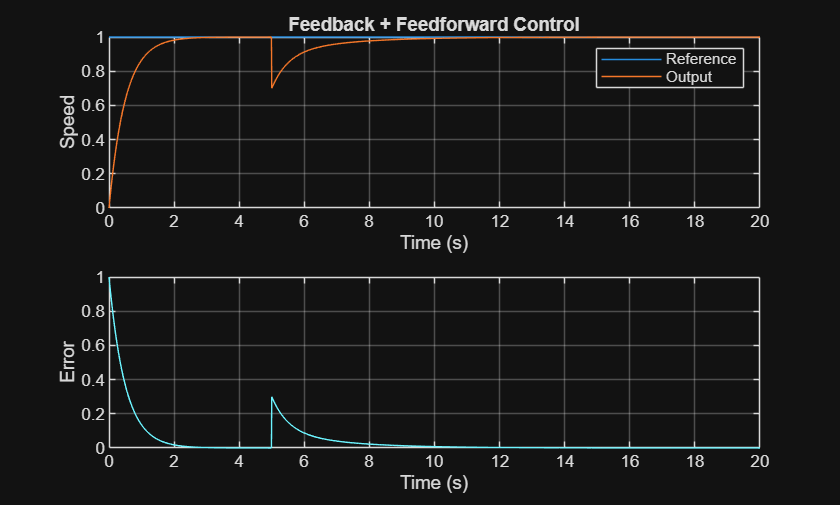

kp = 2; ki = 1;
Cfb = kp + ki/s;
kff = 1 / dcgain(G);
Ff = kff;

T_r = feedback(G * Cfb, 1);
T_d_ff = -(G*Ff + 1) / (1 + G * Cfb);

t = 0:0.01:20;
r = ones(size(t));
d = 0.3 * (t >= 5);

y_r = lsim(T_r, r, t);
y_d = lsim(T_d_ff, d, t);
y_ff = y_r + y_d;

e_ff = r - y_ff;

figure;

subplot(2,1,1)
plot(t, r, t, y_ff)
legend('Reference', 'Output')
xlabel('Time (s)')
ylabel('Speed')
title('Feedback + Feedforward Control')
grid on

subplot(2,1,2)
plot(t, e_ff)
xlabel('Time (s)')
ylabel('Error')
grid on


%% Performance metrics
idx5 = find(t >= 5, 1);

max_error_ff = max(abs(e_ff(idx5:end)));

tol = 0.02;   % 2% tolerance
rec_idx = find(abs(e_ff(idx5:end)) <= tol, 1);
recovery_time_ff = t(idx5 + rec_idx - 1) - 5;

fprintf('With Feedforward Control:\n');

With Feedforward Control:


fprintf('Maximum error = %.4f\n', max_error_ff);

Maximum error = 1.0000


fprintf('Recovery time = %.4f seconds\n', recovery_time_ff);

Recovery time = 3.2500 seconds


P3(c)

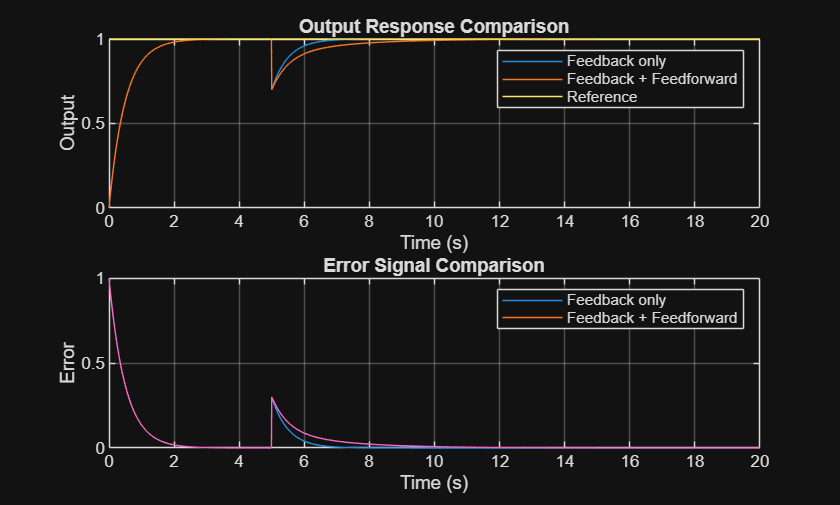

figure ;

subplot(2,1,1);
plot(t, y); hold on;
plot(t, y_ff);
plot(t, r);
legend('Feedback only', 'Feedback + Feedforward', 'Reference');
xlabel('Time (s)');
ylabel('Output');
title('Output Response Comparison');
grid on;

subplot(2,1,2);
plot(t, e); hold on;
plot(t, e_ff);
legend('Feedback only', 'Feedback + Feedforward');
xlabel('Time (s)');
ylabel('Error');
title('Error Signal Comparison');
grid on;



idx5 = find(t >= 5, 1);
tol = 0.02;  % 2% tolerance

max_error_fb = max(abs(e(idx5:end)));
ss_error_fb = abs(mean(e(end-50:end)));

rec_idx_fb = find(abs(e(idx5:end)) <= tol, 1);
recovery_time_fb = t(idx5 + rec_idx_fb - 1) - 5;

max_error_ff = max(abs(e_ff(idx5:end)));
ss_error_ff = abs(mean(e_ff(end-50:end)));

rec_idx_ff = find(abs(e_ff(idx5:end)) <= tol, 1);
recovery_time_ff = t(idx5 + rec_idx_ff - 1) - 5;

PerformanceTable = table( ...
    [max_error_fb; max_error_ff], ...
    [recovery_time_fb; recovery_time_ff], ...
    [ss_error_fb; ss_error_ff], ...
    'VariableNames', {'MaxError', 'RecoveryTime_s', 'SteadyStateError'}, ...
    'RowNames', {'Feedback only', 'Feedback + Feedforward'});

disp(PerformanceTable);

                              MaxError    RecoveryTime_s    SteadyStateError
                              ________    ______________    ________________

    Feedback only             0.30005          1.36            4.8345e-14   
    Feedback + Feedforward          1          3.25            6.2843e-05   



PROBLEM-4

P4(a)

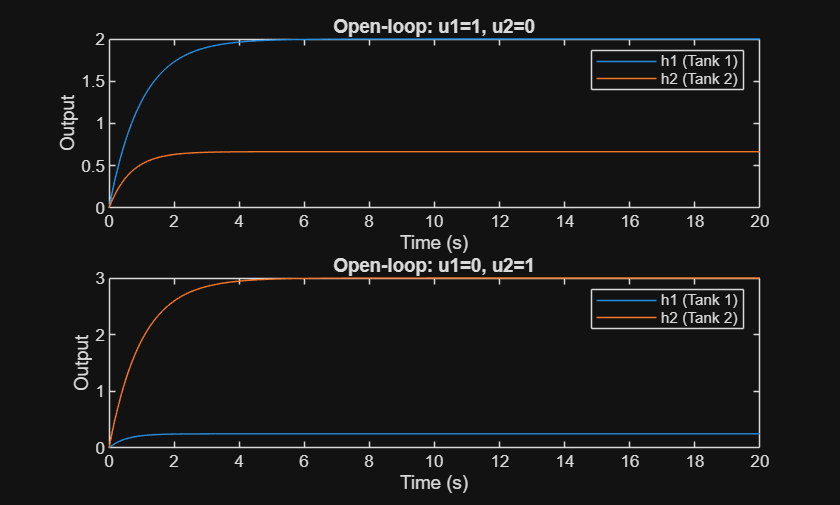

G11 = tf(2, [1 1]);
G12 = tf(0.5, [1 2]);
G21 = tf(1, [1 1.5]);
G22 = tf(3, [1 1]);

G = [G11 G12; G21 G22];
t = 0:0.01:20;
u1 = ones(size(t));
u2 = zeros(size(t));
u = [u1; u2]';
[y, ~] = lsim(G, u, t);

figure;
subplot(2,1,1);
plot(t, y(:,1), t, y(:,2));
legend('h1 (Tank 1)','h2 (Tank 2)');
xlabel('Time (s)'); ylabel('Output');
title('Open-loop: u1=1, u2=0');

u1 = zeros(size(t));
u2 = ones(size(t));
u = [u1; u2]';
[y, ~] = lsim(G, u, t);

subplot(2,1,2);
plot(t, y(:,1), t, y(:,2));
legend('h1 (Tank 1)','h2 (Tank 2)');
xlabel('Time (s)'); ylabel('Output');
title('Open-loop: u1=0, u2=1');

P4(b)

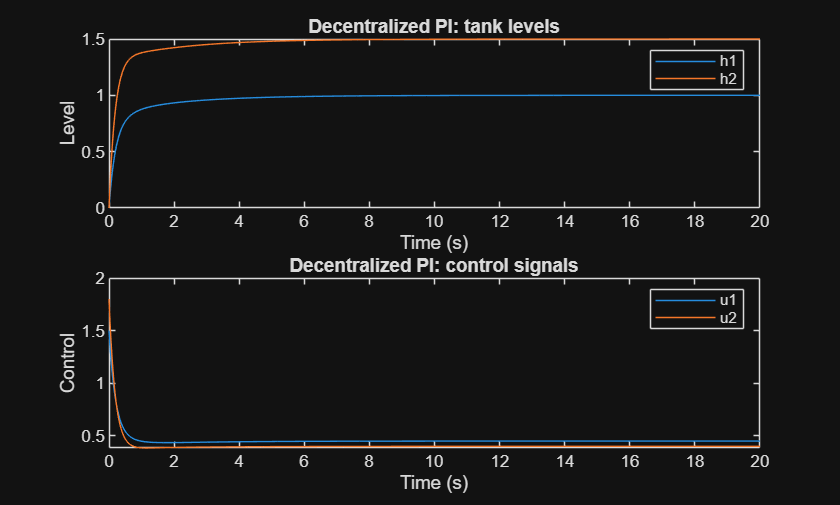

Gd = c2d(G, dt, 'zoh');
[A,B,C,D] = ssdata(Gd);

nx = size(A,1);
x = zeros(nx,1);
h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0; e2_int = 0;
Kp1 = 1.5; Ki1 = 0.8;
Kp2 = 1.2; Ki2 = 0.6;
r1 = 1.0; r2 = 1.5;

for i = 1:length(t)
    yvec = C*x + D*[u1(i); u2(i)];
    h1(i) = yvec(1);
    h2(i) = yvec(2);
    e1 = r1 - h1(i);
    e2 = r2 - h2(i);
    u1(i) = Kp1*e1 + Ki1*e1_int;
    u2(i) = Kp2*e2 + Ki2*e2_int;
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;
    x = A*x + B*[u1(i); u2(i)];
end

figure;
subplot(2,1,1);
plot(t, h1, t, h2);
legend('h1','h2');
xlabel('Time (s)'); ylabel('Level');
title('Decentralized PI: tank levels');
subplot(2,1,2);
plot(t, u1, t, u2);
legend('u1','u2');
xlabel('Time (s)'); ylabel('Control');
title('Decentralized PI: control signals');

P4(c)

x = zeros(nx,1);
h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0; e2_int = 0;
Kp1 = 1.5; Ki1 = 0.8;
Kp2 = 1.2; Ki2 = 0.6;
r1 = 1.0; r2 = 1.5;

for i = 1:length(t)
    yvec = C*x + D*[u1(i); u2(i)];
    h1(i) = yvec(1);
    h2(i) = yvec(2);
    e1 = r1 - h1(i);
    e2 = r2 - h2(i);
    u1(i) = Kp1*e1 + Ki1*e1_int;
    u2(i) = Kp2*e2 + Ki2*e2_int;
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;
    x = A*x + B*[u1(i); u2(i)];
end

tol_perc = 0.02;
final_h1 = mean(h1(end-100:end));
final_h2 = mean(h2(end-100:end));
tol1 = tol_perc*abs(final_h1);
tol2 = tol_perc*abs(final_h2);
settle_idx1 = NaN;
settle_idx2 = NaN;
N = length(t);

for k = 1:N
    if all(abs(h1(k:end)-final_h1) <= tol1)
        settle_idx1 = k; break;
    end
end
for k = 1:N
    if all(abs(h2(k:end)-final_h2) <= tol2)
        settle_idx2 = k; break;
    end
end

settling_time_h1 = t(settle_idx1);
settling_time_h2 = t(settle_idx2);
T = table([final_h1; final_h2],[settling_time_h1; settling_time_h2],...
    'VariableNames', {'FinalValue','SettlingTime_s'},'RowNames',{'h1','h2'});
disp(T);

          FinalValue    SettlingTime_s
          __________    ______________

    h1     0.99998           4.59     
    h2         1.5           4.09     



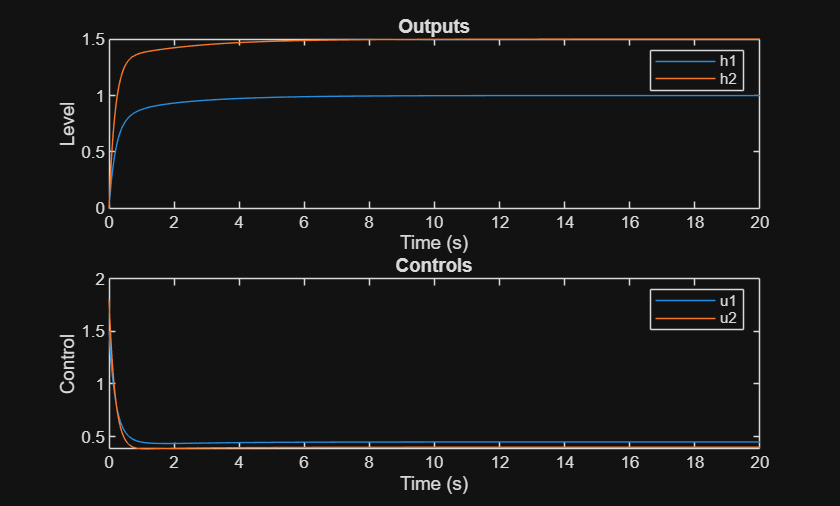


figure;
subplot(2,1,1);
plot(t,h1,t,h2);
legend('h1','h2'); xlabel('Time (s)'); ylabel('Level'); title('Outputs');
subplot(2,1,2);
plot(t,u1,t,u2);
legend('u1','u2'); xlabel('Time (s)'); ylabel('Control'); title('Controls');

P4(d)

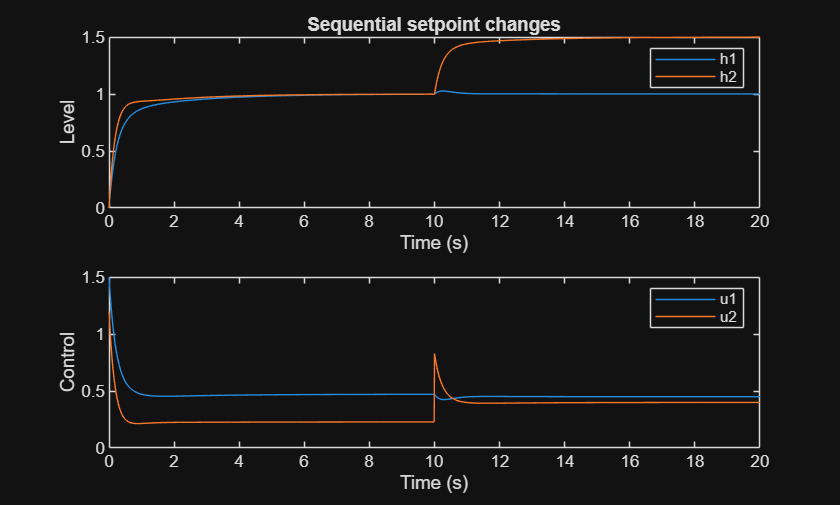

x = zeros(nx,1);
h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0; e2_int = 0;
Kp1 = 1.5; Ki1 = 0.8;
Kp2 = 1.2; Ki2 = 0.6;
r1 = 1.0;

for i = 1:length(t)
    if t(i) < 10
        r2 = 1.0;
    else
        r2 = 1.5;
    end
    yvec = C*x + D*[u1(i); u2(i)];
    h1(i) = yvec(1);
    h2(i) = yvec(2);
    e1 = r1 - h1(i);
    e2 = r2 - h2(i);
    u1(i) = Kp1*e1 + Ki1*e1_int;
    u2(i) = Kp2*e2 + Ki2*e2_int;
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;
    x = A*x + B*[u1(i); u2(i)];
end

figure;
subplot(2,1,1);
plot(t,h1,t,h2);
legend('h1','h2'); xlabel('Time (s)'); ylabel('Level'); title('Sequential setpoint changes');
subplot(2,1,2);
plot(t,u1,t,u2);
legend('u1','u2'); xlabel('Time (s)'); ylabel('Control');